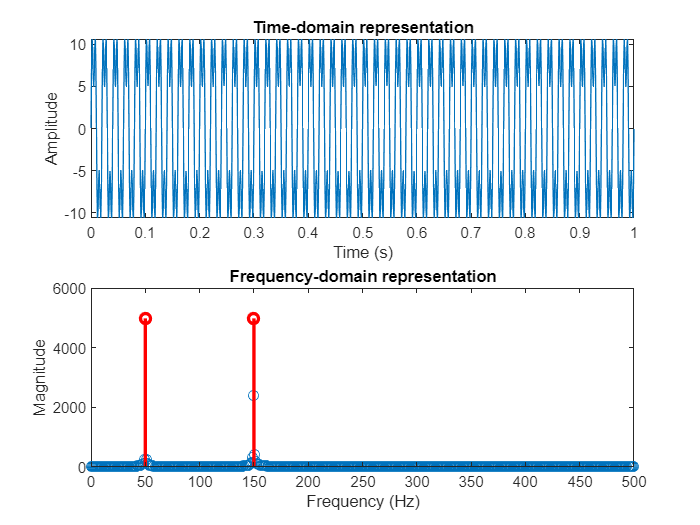

% Generate a harmonic signal
fs = 1000; % Sampling frequency (Hz)
t = 0:1/fs:1; % Time vector (1 second)
f1 = 50; % Fundamental frequency (Hz)
A1 = 10; % Fundamental amplitude
f2 = 150; % Harmonic frequency (Hz)
A2 = 5; % Harmonic amplitude
x = A1*sin(2*pi*f1*t) + A2*sin(2*pi*f2*t);

% Perform Fourier analysis
N = length(x); % Length of the signal
X = fft(x); % Compute the Fourier transform
X_mag = abs(X); % Magnitude spectrum
f = (0:N-1)*(fs/N); % Frequency vector

% Plot the signal in time domain
subplot(2,1,1);
plot(t, x);
xlabel('Time (s)');
ylabel('Amplitude');
title('Time-domain representation');

% Plot the magnitude spectrum
subplot(2,1,2);
stem(f, X_mag);
xlim([0 fs/2]);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency-domain representation');

% Highlight harmonic frequencies
hold on;
stem(f1, max(X_mag), 'r', 'LineWidth', 2);
stem(f2, max(X_mag), 'r', 'LineWidth', 2);
hold off;

## 1

% Specify the file path of the CSV dataset
file = 'path/to/your/dataset.csv';

% Load the CSV dataset
data = readmatrix(file); % or csvread(file) for older MATLAB versions

Error using readmatrix (line 158)
Unable to find or open 'path/to/your/dataset.csv'. Check the path and filename or file permissions.


% Extract the harmonic signal from the dataset
x = data; % Assuming the dataset is stored in a variable named 'data'

% Perform Fourier analysis
N = length(x); % Length of the signal
fs = 1000; % Sampling frequency (Hz)
X = fft(x); % Compute the Fourier transform
X_mag = abs(X); % Magnitude spectrum
f = (0:N-1)*(fs/N); % Frequency vector

% Plot the signal in time domain
subplot(2,1,1);
t = (0:N-1)/fs; % Time vector
plot(t, x);
xlabel('Time (s)');
ylabel('Amplitude');
title('Time-domain representation');

% Plot the magnitude spectrum
subplot(2,1,2);
stem(f, X_mag);
xlim([0 fs/2]);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency-domain representation');
